Setuo

A = load('MatlabGiven/mat1.txt');
sol = sort(eig(A), 'descend');

QR iteratie zonder shifts

[E1, res_zonder] = qr_zondershift(A);
norm_res_zonder = zeros(size(res_zonder, 2), 1);
for i = 1:size(res_zonder,2)
    norm_res_zonder(i) = norm(res_zonder(:, i));
end
norm_res_zonder

norm_res_zonder =    26.1465
   25.0916
   23.4574
   22.0728
   20.9219
   19.7402
   18.0620
   17.1553
   15.8974
   14.9992


QR iteratie  met Rayleigh quotient shift

[E2, res_ray] = qr_rayleighshift(A);
norm_res_ray = zeros(size(res_ray, 2), 1);
for i = 1:size(res_ray, 2)
    norm_res_ray(i) = norm(res_ray(:, i));
end
norm_res_ray

norm_res_ray =    26.1465
   25.0718
   23.8239
   22.7611
   21.5106
   19.8150
   19.3316
   17.6018
   17.6164
   15.8072


QR iteratie met Wilkinson shift

[E3, res_wilk] = qr_wilkinsonshift(A);
norm_res_wilk = zeros(size(res_wilk, 2), 1);
for i = 1:size(res_wilk, 2)
    norm_res_wilk(i) = norm(res_wilk(:, i));
end
norm_res_wilk

norm_res_wilk =    26.1465
   25.0716
   23.8239
   22.7593
   21.5600
   19.7584
   19.0204
   17.7774
   17.0233
   15.6590


Plotten

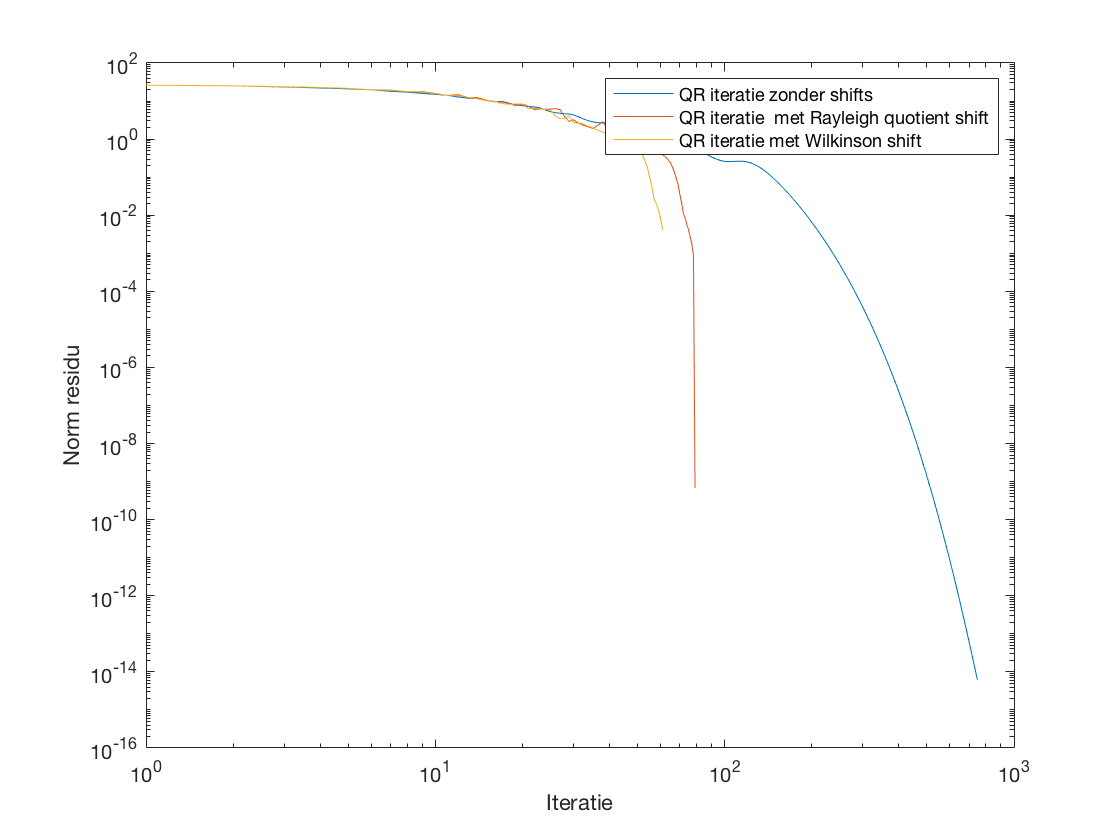

figure
loglog(norm_res_zonder);
hold on;
loglog(norm_res_ray);
loglog(norm_res_wilk);
legend('QR iteratie zonder shifts', 'QR iteratie  met Rayleigh quotient shift', 'QR iteratie met Wilkinson shift');
xlabel('Iteratie');
ylabel('Norm residu');